# Underapproximative verification of an automated anesthesia delivery system

This example will demonstrate the use of [SReachTools](https://abyvinod.github.io/SReachTools/) in verification and controller synthesis for stochastic continuous-state discrete-time linear time-invariant (LTI) systems. In this example, we will verify an automated anesthesia delivery model.

## Notes about this Live Script:

- **MATLAB dependencies**: This Live Script uses MATLAB's [Global Optimization Toolbox](https://www.mathworks.com/products/global-optimization.html), and [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html). 

- **External dependencies**: This Live Script uses Multi-Parameteric Toolbox ([MPT](http://people.ee.ethz.ch/~mpt/3/)) and [CVX](http://cvxr.com/cvx/). 

- We will also [Genz's algorithm](http://www.math.wsu.edu/faculty/genz/software/matlab/qsimvnv.m) (included in helperFunctions of SReachTools) to evaluate integrals of a Gaussian density over a polytope.

- Make sure that `srtinit` is run before running this script.

This Live Script is part of the SReachTools toolbox. License for the use of this function is given in [https://github.com/abyvinod/SReachTools/blob/master/LICENSE.](https://github.com/abyvinod/SReachSReachTools/blob/master/LICENSE.)

## Problem Formulation

We first define a `LtiSystem` object corresponding to the discrete-time approximation of the three-compartment pharmacokinetic system model.

systemMatrix = [0.8192, 0.03412, 0.01265;
                0.01646, 0.9822, 0.0001;
                0.0009, 0.00002, 0.9989];
inputMatrix = [0.01883;
               0.0002;
               0.00001];
% Automation input bounds
auto_input_max = 7;  

% Process disturbance with a specified mean and variance
dist_mean = 0;
dist_var = 5;
process_disturbance = StochasticDisturbance('Gaussian',...
                                            dist_mean, ...
                                            dist_var);
% LtiSystem definition                                        
sys = LtiSystem('StateMatrix', systemMatrix, ...
                'InputMatrix', inputMatrix, ...
                'DisturbanceMatrix', inputMatrix, ...
                'InputSpace', Polyhedron('lb', 0, 'ub', auto_input_max), ...
                'Disturbance', process_disturbance);
disp(sys)            

LTI System with 3 states, 1 input, 1 disturbance


## Safety specifications

We desire that the state remains inside a set $\mathcal{K}=\{x\in \mathbf{R}^3: 0\leq x_1 \leq 6, 0\leq x_2 \leq 10, 0\leq x_3 \leq 10 \}$.

time_horizon = 5;
safe_set = Polyhedron('lb',[1, 0, 0], 'ub', [6, 10, 10]);

## Computation of polytopic underapproximation

%% Definition of the affine hull
x3_initial_state = 5;
affine_hull_of_interest_2D_A = [zeros(2,3); 0, 0, 1];
affine_hull_of_interest_2D_b = [zeros(2,1);x3_initial_state];
affine_hull_of_interest_2D = Polyhedron('He',...
                                        [affine_hull_of_interest_2D_A,...
                                         affine_hull_of_interest_2D_b]);
probability_threshold_of_interest = 0.99;     % Stochastic reach-avoid 'level' of interest
no_of_direction_vectors = 8;                 % Increase for a tighter polytopic
                                             % representation at the cost of higher 
                                             % computation time
tolerance_bisection = 1e-2;                  % Tolerance for bisection to compute the 
                                             % extension
%% Parameters for MATLAB's Global Optimization Toolbox patternsearch
desired_accuracy = 1e-3;                     % Decrease for a more accurate lower 
                                             % bound at the cost of higher 
                                             % computation time
PSoptions = psoptimset('Display','off');
timer_val = tic;
[underapproximate_stochastic_reach_avoid_polytope,...
 optimal_input_vector_at_boundary_points,...
 xmax,...
 optimal_input_vector_for_xmax,...
 maximum_underapproximate_reach_avoid_probability,...
 optimal_theta_i,...
 optimal_reachAvoid_i] =...
          getUnderapproxStochReachAvoidSet(sys,...
                                           time_horizon,...
                                           safe_set,...
                                           safe_set,...
                                           probability_threshold_of_interest,...
                                           tolerance_bisection,...
                                           no_of_direction_vectors,...
                                           affine_hull_of_interest_2D,...
                                           desired_accuracy,...
                                           PSoptions);

Computing the x_max for the Fourier transform-based underapproximation
Polytopic underapproximation exists for alpha = 0.99 since W(x_max) = 1.000.

Analyzing direction (shown transposed) :1/8
     0     1     0

Upper bound of theta: 4.67
OptRAProb | OptTheta | LB_theta | UB_theta | OptInp^2 | Exit reason
  1.0000  |  2.3373  |  0.0000  |  4.6746  |  0.0000  | Feasible 
  1.0000  |  3.5059  |  2.3373  |  4.6746  |  0.0000  | Feasible 
  1.0000  |  4.0903  |  3.5059  |  4.6746  |  0.0000  | Feasible 
  1.0000  |  4.3824  |  4.0903  |  4.6746  |  0.0000  | Feasible 
  1.0000  |  4.5285  |  4.3824  |  4.6746  |  0.0000  | Feasible 
  1.0000  |  4.6015  |  4.5285  |  4.6746  |  0.0000  | Feasible 
  1.0000  |  4.6381  |  4.6015  |  4.6746  |  0.0000  | Feasible 
  1.0000  |  4.6563  |  4.6381  |  4.6746  |  0.0000  | Feasible 
  1.0000  |  4.6654  |  4.6563  |  4.6746  |  0.0000  | Feasible 
Analyzing direction (shown transposed) :2/8
   -0.7071    0.7071         0

Upper bound of theta: 

elapsed_time = toc(timer_val);
disp(elapsed_time)

   76.2916



This approach is computationally efficient as well. 

Construct the 2D representation of the underapproximative polytope.

set_of_direction_vectors = computeDirectionVectors(no_of_direction_vectors,...
                                                   sys.state_dimension,...
                                                   affine_hull_of_interest_2D);
vertex_poly = xmax + optimal_theta_i.* set_of_direction_vectors;
underapproximate_stochastic_reach_avoid_polytope_2D =...
                                            Polyhedron('V',vertex_poly(1:2,:)');                                       

## Plotting

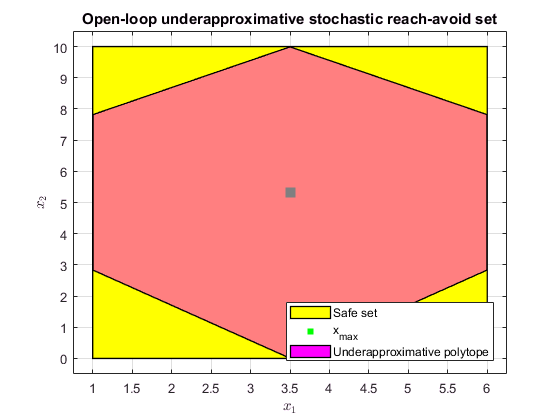

figure();
hold on;
plot(safe_set.slice(3, x3_initial_state), 'color', 'y');
scatter(xmax(1), xmax(2), 100,'gs','filled')
if ~isEmptySet(underapproximate_stochastic_reach_avoid_polytope)
    plot(underapproximate_stochastic_reach_avoid_polytope_2D,...
         'color','m','alpha',0.5);
    leg=legend({'Safe set',...
            'x_{max}',...
            'Underapproximative polytope'});
else
    leg=legend({'Safe set','x_{max}'})
end
set(leg,'Location','SouthEast');
xlabel('$x_1$','interpreter','latex')
ylabel('$x_2$','interpreter','latex')
box on;
grid on;
title('Open-loop underapproximative stochastic reach-avoid set');

## Validate the underapproximative set and the controllers synthesized using Monte-Carlo simulations

We will now check how the optimal policy computed for each corners perform in Monte-Carlo simulations.

Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 1.000, 1.000


Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 1.000, 1.000


Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 1.000, 0.999


Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 0.997, 0.997


Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 1.000, 1.000


Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 1.000, 1.000


Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 1.000, 1.000


Open-loop-based lower bound and Monte-Carlo simulation (1e+05 particles): 1.000, 1.000


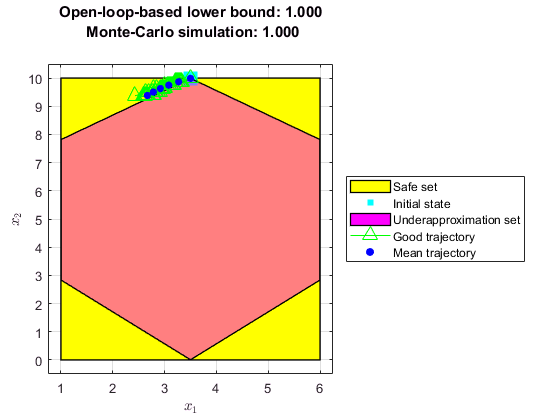

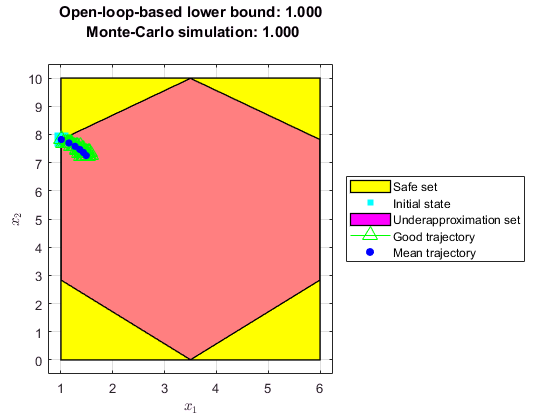

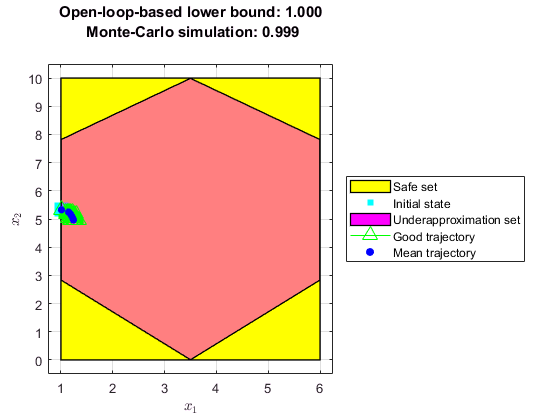

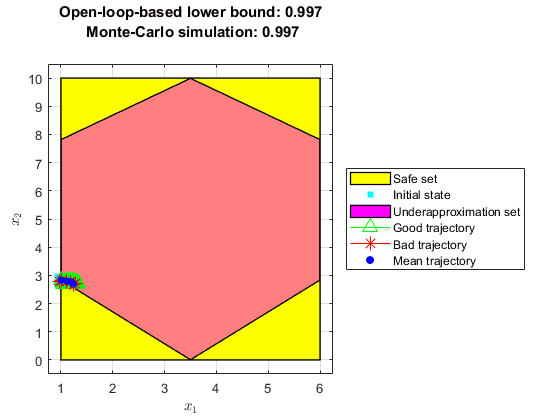

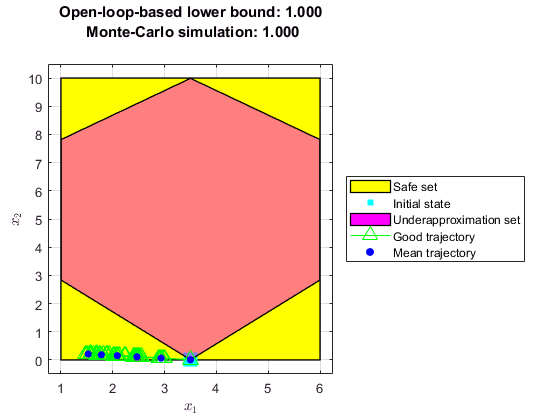

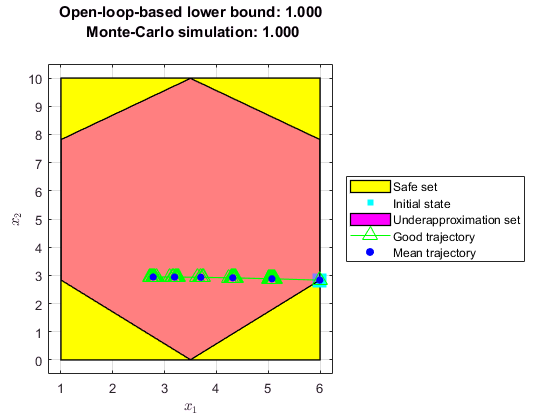

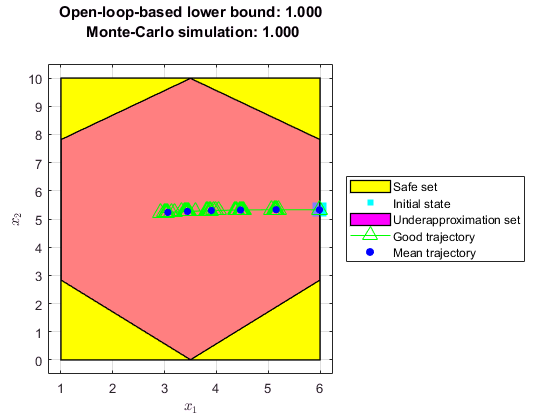

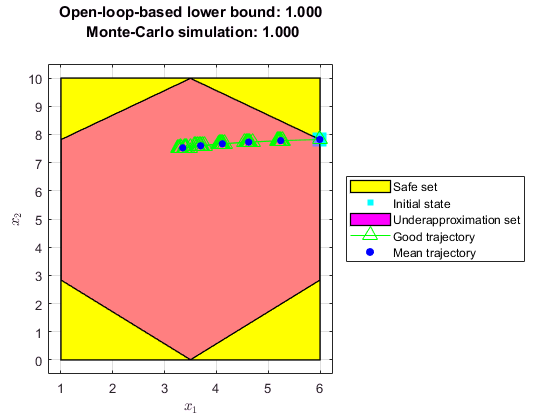

no_mcarlo_sims = 1e5;
no_sims_to_plot = 10;
if ~isEmptySet(underapproximate_stochastic_reach_avoid_polytope)
    for direction_index = 1:no_of_direction_vectors
        figure();
        hold on;
        plot(safe_set.slice([3], x3_initial_state), 'color', 'y');
        scatter(vertex_poly(1,direction_index),...
                vertex_poly(2,direction_index),...
                200,'cs','filled');
        plot(underapproximate_stochastic_reach_avoid_polytope_2D,...
             'color','m','alpha',0.5);
        legend_cell = {'Safe set', ...
                       'Initial state',...
                       'Underapproximation set'};

        [reach_avoid_probability_mcarlo,...
         legend_cell] = checkViaMonteCarloSims(...
                 no_mcarlo_sims,...
                 sys,...
                 vertex_poly(:,direction_index),...
                 time_horizon,...
                 safe_set,...
                 safe_set,...
                 optimal_input_vector_at_boundary_points(:, direction_index),...
                 legend_cell,...
                 no_sims_to_plot);
        % Compute and plot the mean trajectory under the optimal open-loop
        % controller from the the vertex under study
        [H_matrix, mean_X_sans_input, ~] =...
         getHmatMeanCovForXSansInput(sys,...
                                     vertex_poly(:,direction_index),...
                                     time_horizon);
        optimal_mean_X = mean_X_sans_input + H_matrix *...
                    optimal_input_vector_at_boundary_points(:, direction_index);
        optimal_mean_trajectory=reshape(optimal_mean_X,sys.state_dimension,[]);
        % Plot the optimal mean trajectory from the vertex under study
        scatter(...
              [vertex_poly(1,direction_index), optimal_mean_trajectory(1,:)],...
              [vertex_poly(2,direction_index), optimal_mean_trajectory(2,:)],...
              30, 'bo', 'filled');
        legend_cell{end+1} = 'Mean trajectory';
        leg = legend(legend_cell,'Location','EastOutside');
        % title for the plot
        if no_sims_to_plot > 0
            title(sprintf(['Open-loop-based lower bound: %1.3f\n Monte-Carlo ',...
                           'simulation: %1.3f\n'],...
                optimal_reachAvoid_i(direction_index),...
                round(reach_avoid_probability_mcarlo / desired_accuracy) *...
                    desired_accuracy));
        end
        box on;
        grid on;
        xlabel('$x_1$','interpreter','latex')
        ylabel('$x_2$','interpreter','latex')
        
        fprintf(['Open-loop-based lower bound and Monte-Carlo simulation ',...
                 '(%1.0e particles): %1.3f, %1.3f\n'],...
                no_mcarlo_sims,...
                optimal_reachAvoid_i(direction_index),...
                round(reach_avoid_probability_mcarlo / desired_accuracy) *...
                    desired_accuracy);
    end
end